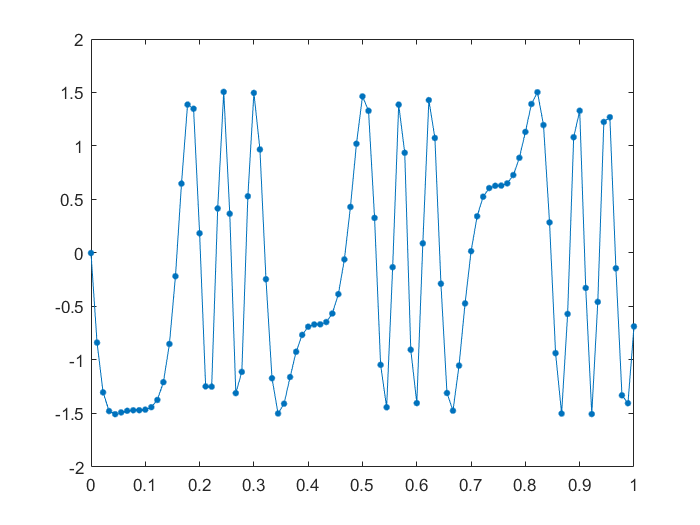

phai0=pi;
f0=3*pi;
f1=3;
A = 1;
snr_AM = 10;
% Instantaneous frequency after 1 sec is 
maxFreq = f1+(f0/2.0)/pi;
samplFreq = 20*maxFreq;
samplIntrvl = 1/samplFreq;

% Time samples
timeVec = 0:samplIntrvl:1.0;
% Number of samples
nSamples = length(timeVec);

% Generate the signal
sigVec = crcbgenFMsig(timeVec,snr_AM,[A,phai0,f0,f1]);

%Plot the signal 
figure;
plot(timeVec,sigVec,'Marker','.','MarkerSize',12);

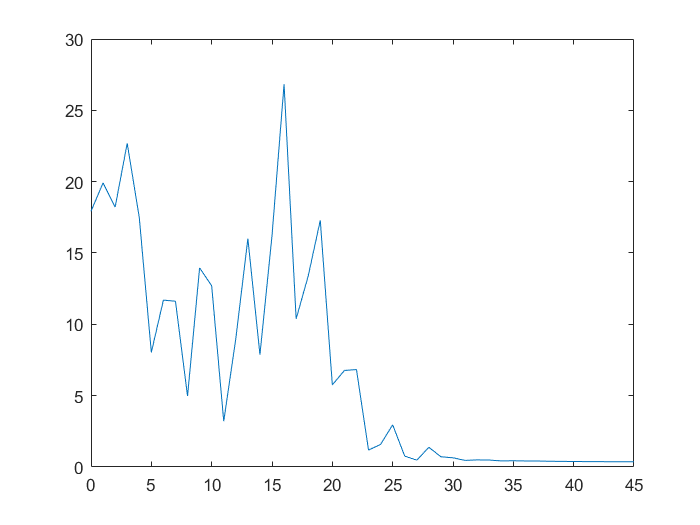


%Plot the periodogram
%--------------
%Length of data 
dataLen = timeVec(end)-timeVec(1);
%DFT sample corresponding to Nyquist frequency
kNyq = floor(nSamples/2)+1;
% Positive Fourier frequencies
posFreq = (0:(kNyq-1))*(1/dataLen);
% FFT of signal
fftSig = fft(sigVec);
% Discard negative frequencies
fftSig = fftSig(1:kNyq);

%Plot periodogram
figure;
plot(posFreq,abs(fftSig));

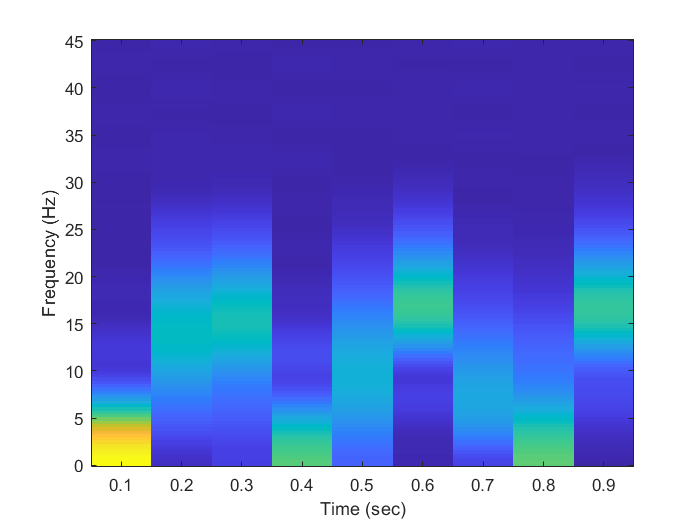


%Plot a spectrogram
%----------------
winLen = 0.2;%sec
ovrlp = 0.1;%sec
%Convert to integer number of samples 
winLenSmpls = floor(winLen*samplFreq);
ovrlpSmpls = floor(ovrlp*samplFreq);
[S,F,T]=spectrogram(sigVec,winLenSmpls,ovrlpSmpls,[],samplFreq);
figure;
imagesc(T,F,abs(S)); axis xy;
xlabel('Time (sec)');
ylabel('Frequency (Hz)');